# **PESTools - Example 020 - PES Data Processing**

## Author: PCC

The example shows how to use PESTools to fit the data from an PES experiment using a model that consists of a linear combination of N curves and a global optimisation method to minimise residuals.

For a more in-depth explanation of potential in- and output of those functions, consult the UserGuide.

For external data files, all you need to do is define the **x-axis (binding energy)** and **y-axis (intensity) **and all the fitting tools are available to use. This means you can in principle import any type of data you like, even a text file. To be compatible, all you need to do is define a matlab struct(), for example 'PES_dat{1}', with **two** fields:

- Define the **x-axis data** as:    PES_dat{1}**.xdat**

- Deine the **y-axis data **as:     PES_dat{1}**.ydat**

close all; clear all;
pp          = plot_props();
data_path   = 'D:\OneDrive\PCC_MS_Project\00_Software_Library\ADRESSTools\ADRESSTools_Basil\PESTools_PCC\Examples\Example_Data\';
save_path   = 'D:\OneDrive\PCC_MS_Project\00_Software_Library\ADRESSTools\ADRESSTools_Basil\PESTools_PCC\Examples\Example_Data\';

# **PES Data Processing**

**(A) Loading in the PES data files**

% % Defining many file-names through a keyword
% all_files       = dir(data_path);
% all_files       = {all_files(~[all_files.isdir]).name};
% findx           = find(contains(all_files, "020_XPS_In4d_hv="));
% file_names      = sort(all_files(findx));
% Explicitely defining the file-names
file_names      = {...
    '020_XPS_In4d_hv=550eV.h5',...
    '020_XPS_In4d_hv=750eV.h5',...
    '020_XPS_In4d_hv=950eV.h5',...
    '020_XPS_In4d_hv=1150eV.h5',...
    };
% Load in the data
PES_dat = cell(1,length(file_names));
for i = 1:length(file_names); PES_dat{i} = load_adress_data(file_names{i}, data_path); end

Loading ARPES data...
Loading ARPES data...
Loading ARPES data...
Loading ARPES data...


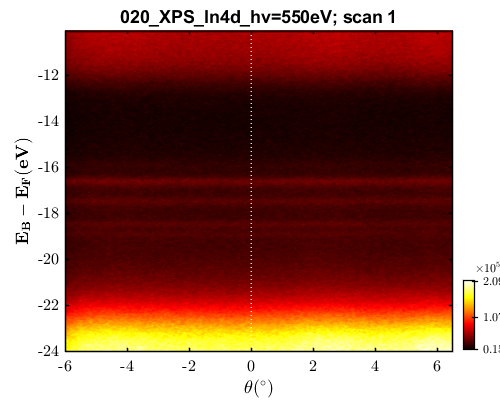

view_data(PES_dat{1});

**(B) Loading in the Fermi edge reference via gold / copper**

Note, that all PES data should come with a Fermi-edge reference so that the binding energy scale can be properly calibrated.

% % Defining many file-names through a keyword
% all_files       = dir(data_path);
% all_files       = {all_files(~[all_files.isdir]).name};
% findx           = find(contains(all_files, "eV_EF.h5"));
% file_names_ef     = sort(all_files(findx));
% Explicitely defining the file-names
file_names_ef      = {...
    '020_XPS_In4d_hv=550eV_EF.h5',...
    '020_XPS_In4d_hv=750eV_EF.h5',...
    '020_XPS_In4d_hv=950eV_EF.h5',...
    '020_XPS_In4d_hv=1150eV_EF.h5',...
    };
% Load in the data
PES_ref = cell(1,length(file_names_ef));
for i = 1:length(file_names_ef); PES_ref{i} = load_adress_data(file_names_ef{i}, data_path); end

Loading ARPES data...
Loading ARPES data...
Loading ARPES data...
Loading ARPES data...


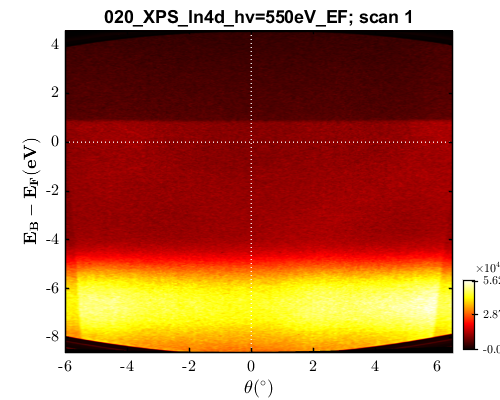

view_data(PES_ref{1});

**(C) Binding energy alignment to the reference data**

- EF alignment


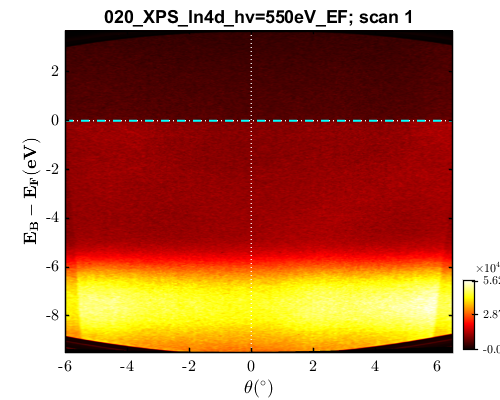

- EF alignment


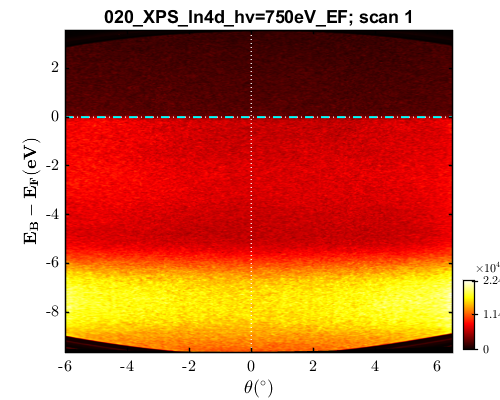

- EF alignment


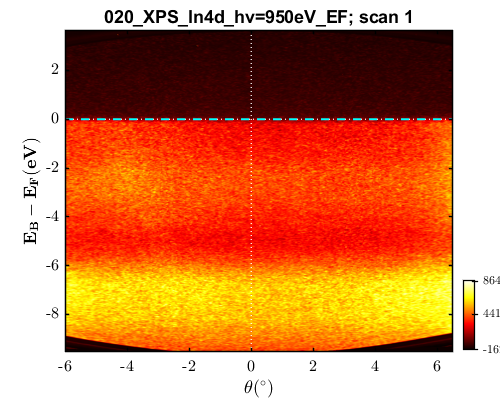

- EF alignment


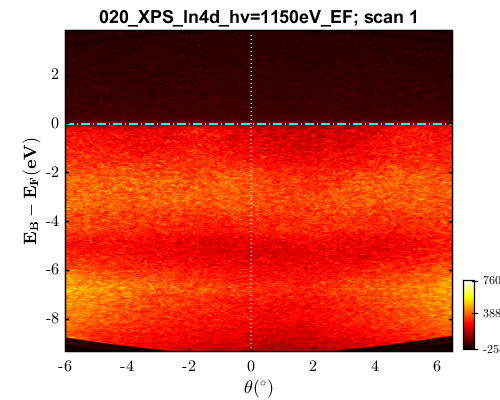

% (1) AUTOMATIC COARSE ALIGNMENT TO THE EDGE OF THE REFERENCE
% -- Coarse alignment of the energy
alignType   = "ref";        % either "global", "global shift via scan", "scans", "ref", "ref (per channel)", "fit2ref"
scan_indxs	= [];               % for "global" or "ref" it is empty []. For "scans", it defines the scan indices to perform alignment on.
eWin        = 0.00;                % approximate EF position. Can be a single, constant value. If a vector, it linear interpolates estimates between [firstEF, endEF].
dEWin       = 4.00;              % can be empty []. Single, constant value that defines the width of the EF.
dESmooth    = [];               % can be empty []. Single, constant value that defines Gaussian pre-smoothing energy width.
feat        = 'edge';           % either 'edge' or 'peak'. defines the feature to align as a 'peak' instead of the default Fermi 'edge'.
align_args  = {alignType, scan_indxs, eWin, dEWin, dESmooth, feat};
for i = 1:length(PES_dat)
    PES_dat{i}  = align_energy(PES_dat{i}, align_args, PES_ref{i}); 
    PES_ref{i}.raw_eb = PES_ref{i}.raw_eb - PES_dat{i}.eb_shifts{1};
    view_data(PES_ref{i});
    line([-1e3, 1e3], [0, 0], 'color', 'c', 'linewidth', 1.5, 'linestyle', '--'); 
end

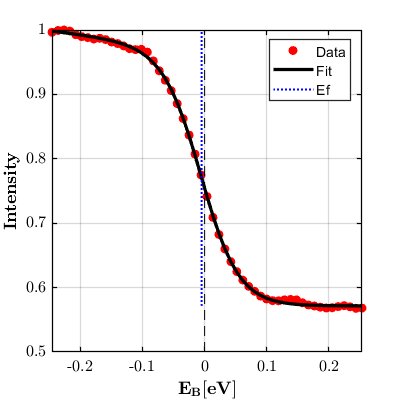

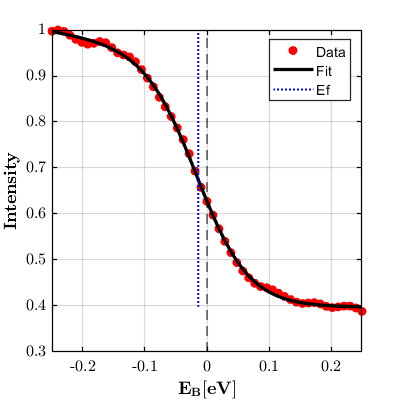

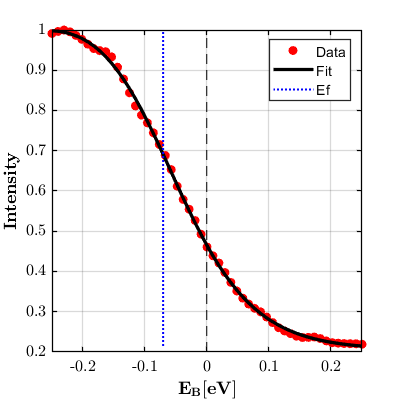

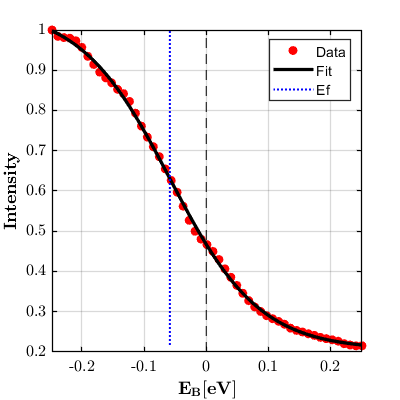

% (2) FITTING TO THE FDD WITH FINE ALIGNMENT
alignType   = "fit2ref";        % either "global", "global shift via scan", "scans", "ref", "ref (per channel)", "fit2ref"
scan_indxs	= [];               % for "global" or "ref" it is empty []. For "scans", it defines the scan indices to perform alignment on.
eWin        = 0.00;                % approximate EF position. Can be a single, constant value. If a vector, it linear interpolates estimates between [firstEF, endEF].
dEWin       = 0.25;              % can be empty []. Single, constant value that defines the width of the EF.
dESmooth    = [];               % can be empty []. Single, constant value that defines Gaussian pre-smoothing energy width.
feat        = 'edge';           % either 'edge' or 'peak'. defines the feature to align as a 'peak' instead of the default Fermi 'edge'.
align_args  = {alignType, scan_indxs, eWin, dEWin, dESmooth, feat};
for i = 1:length(PES_dat)
    PES_dat{i}  = align_energy(PES_dat{i}, align_args, PES_ref{i}); 
end

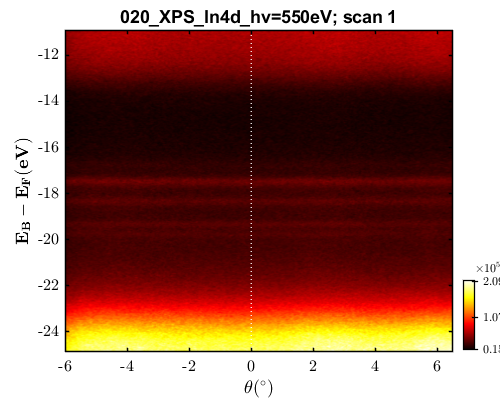

view_data(PES_dat{1});
line([-1e3, 1e3], [0, 0], 'color', 'c', 'linewidth', 1.5, 'linestyle', '--'); 

**(D) Extract the PES data by angle-integrating the ARPES spectrum**

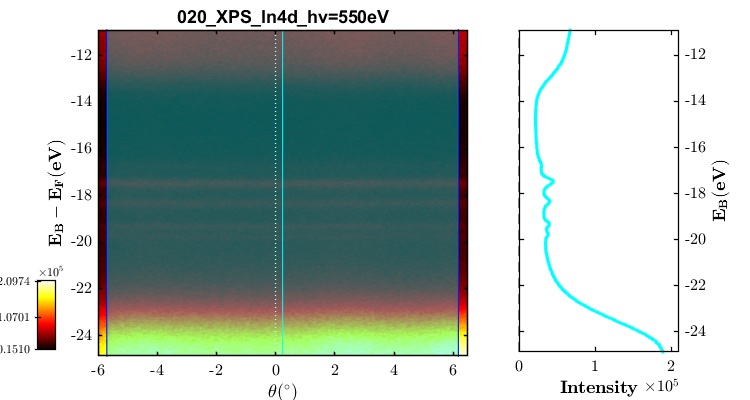

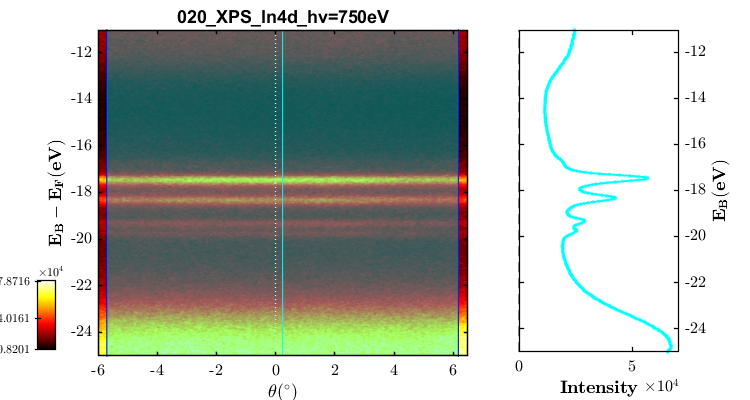

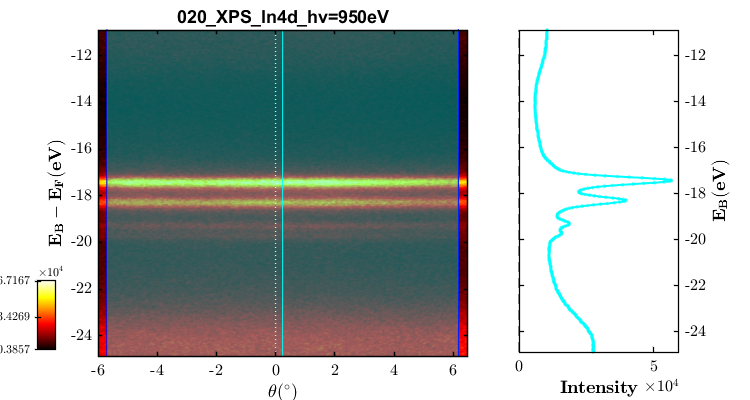

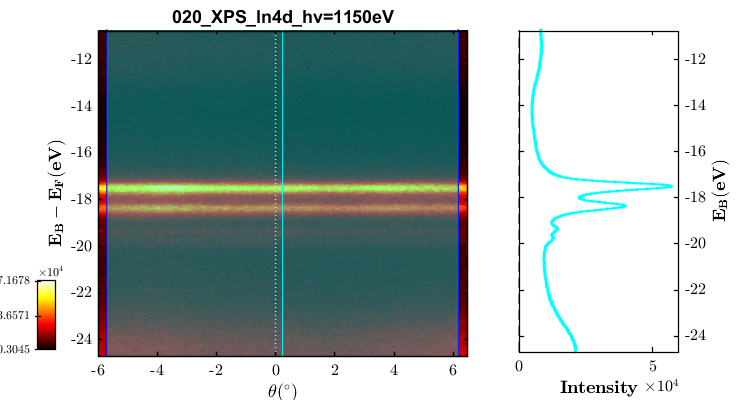

cutWin          = 0.95*[min(PES_dat{1}.tht(:)), max(PES_dat{1}.tht(:))];    % Integration window of the cut to be made.
cutN            = 1;                                                        % Single, constant value that determines the total number of line profiles to extract
xps_args        = {cutWin, cutN};
for i = 1:length(PES_dat)
    [PES_dat{i}, ~]     = pes_extract_data(PES_dat{i}, xps_args);
end

if length(PES_dat{i}) > 1; PES_dat = [PES_dat{:}]; end
view_data(PES_dat{1});

**(E) Comparing the peak positions vs measurements**

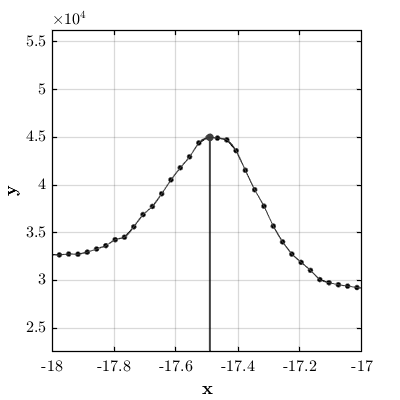

1) x = -17.49 eV, y = 45000.27 


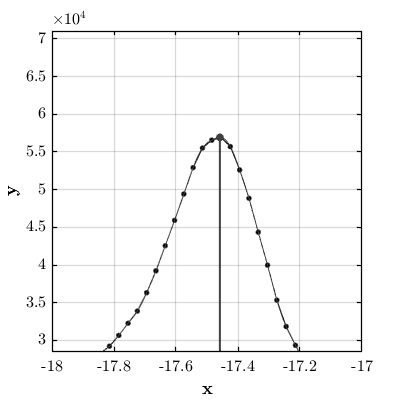

1) x = -17.46 eV, y = 56937.89 


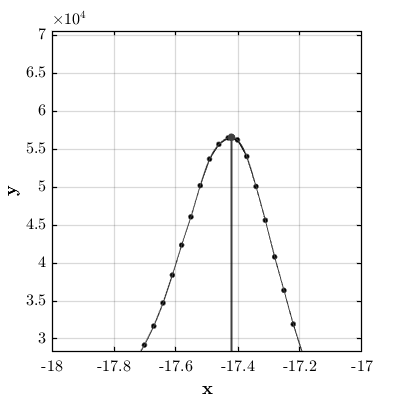

1) x = -17.42 eV, y = 56570.62 


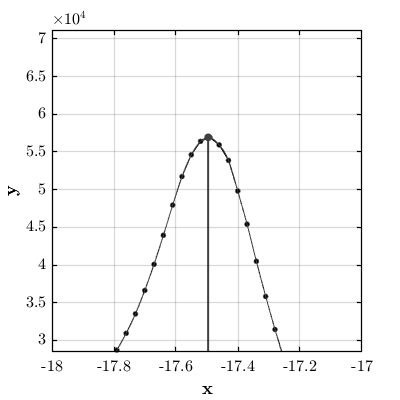

1) x = -17.50 eV, y = 56945.20 


% -- Extracting the energy and intensity of the peak positions
PES_xVal    = [];
PES_yVal    = [];
xWin            = -17.5 + [-0.50, 0.50];
for i = 1:length(PES_dat); [PES_xVal(i), PES_yVal(i)] = find_peak_loc(PES_dat{i}.xdat, PES_dat{i}.ydat, xWin, 'spline'); end

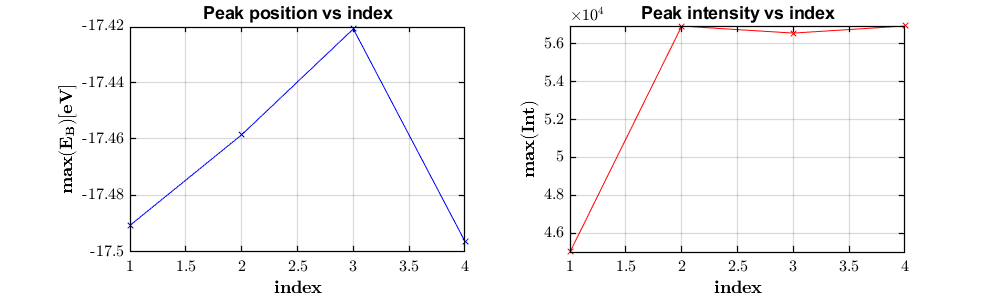

% -- Plotting the comparison
fig1 = figure(); 
fig1.Position(3) = 2.0*500;
fig1.Position(4) = 1.0*300;
% -- Plotting the Peak Eb position vs Photon Energy
subplot(121); hold on;
plot(1:length(PES_xVal), PES_xVal, 'bx-');
% - Formatting the figure
% axis padded; 
gca_props(); grid on;
xlabel('$$ \bf  index $$', 'Interpreter', 'latex');
ylabel('$$ \bf  max(E_B) [eV] $$', 'Interpreter', 'latex');
title("Peak position vs index");
% -- Plotting the Peak Intensity vs Photon Energy
subplot(122); hold on;
plot(1:length(PES_xVal), PES_yVal, 'rx-');
% - Formatting the figure
% axis padded; 
gca_props(); grid on;
xlabel('$$ \bf  index $$', 'Interpreter', 'latex');
ylabel('$$ \bf  max(Int) $$', 'Interpreter', 'latex');
title("Peak intensity vs index");

**(F) Crop around the region of interest**

As you can see from above, the background is quite large, so we would like to crop the data over the binding energy range of interest. 

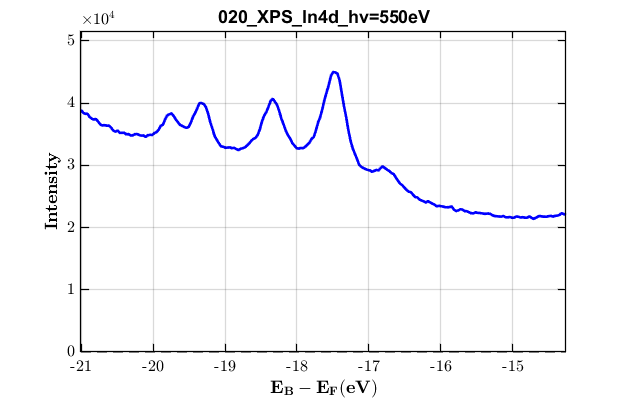

ebLims = -17.5 + [-3.50, 3.25];
for i = 1:length(PES_dat)
    [~, PES_dat{i}.xdat, PES_dat{i}.ydat] = data_crop2D([], PES_dat{i}.xdat, PES_dat{i}.ydat, [], ebLims);
end
view_pes_data(PES_dat{1});

**(G) Normalisation of the PES spectrum**

One of the most common processing that is done on PES data is to renormalise the data so that its minimum is at zero and maximum at one. Although not necessary, we do this here as it simplifies the initial conditions of the PES fitting algorithm to reasonable values of intensities. To normalise the PES data, we use the 'normalise_xps()' function and define a peak that we treat as the normalisation peak. 

ans = "xval = -17.50 eV, yval = 23601.51"

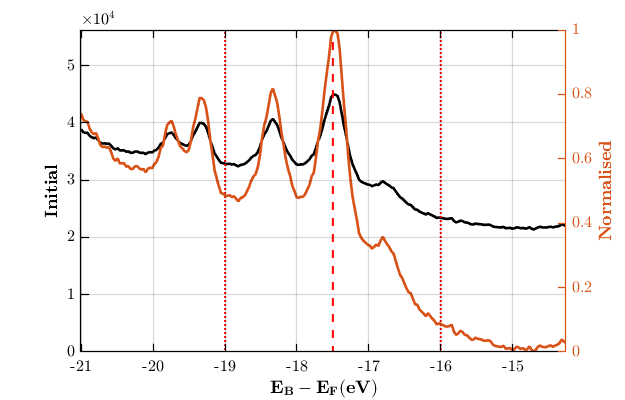

ans = "xval = -17.45 eV, yval = 45644.46"

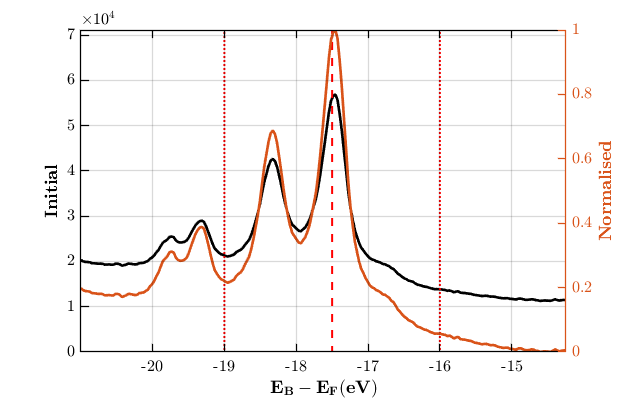

ans = "xval = -17.43 eV, yval = 50563.89"

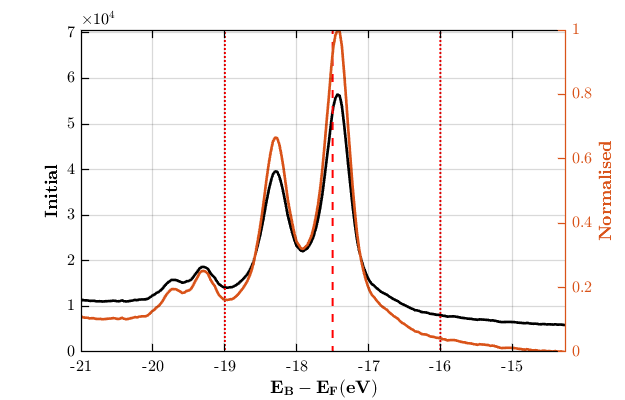

ans = "xval = -17.49 eV, yval = 52085.37"

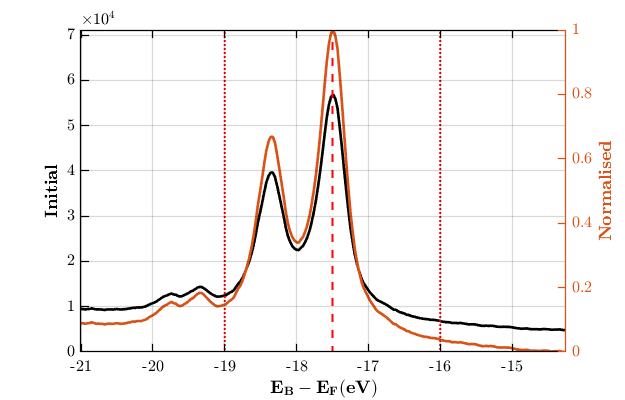

eWin            = -17.5;        % approximate Eb position of a peak in the spectrum to normalise to.
dEWin           = 1.5;          % can be empty []. Single, constant value that defines the width of the approximate Eb position
norm_args    = {eWin, dEWin};
for i = 1:length(PES_dat)
    PES_dat{i}.ydat = pes_norm2peak(PES_dat{i}.xdat, PES_dat{i}.ydat, norm_args, 1);
end

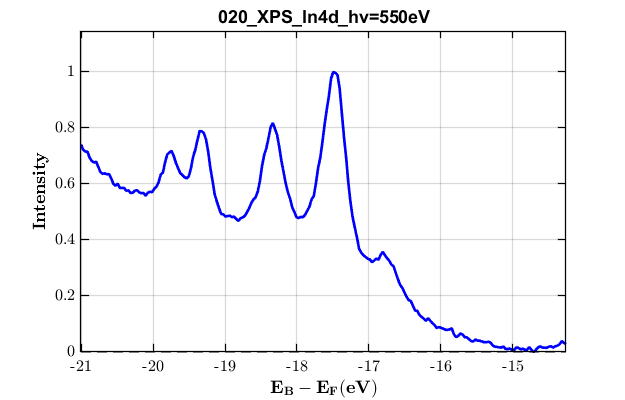

view_pes_data(PES_dat{1});

**(H) Final data structure after all the processing**

view_pes_data(PES_dat); PES_dat{1}

ans = struct with fields:
       FileName: '020_XPS_In4d_hv=550eV'
         H5file: '020_XPS_In4d_hv=550eV.h5'
           Type: "Eb(k)"
           meta: [1×1 struct]
       raw_data: [467×391 double]
        raw_tht: [1×391 double]
         raw_eb: [467×1 double]
            deb: 0.0500
             hv: 550
            dhv: 0.0750
           tltM: 0
           thtM: 0
           Temp: 5.5000
      eb_shifts: {[0.8809]  [-0.0047]}
    eb_ref_file: '020_XPS_In4d_hv=550eV_EF'
             eb: [467×391 double]
            tht: [467×391 double]
        IsoType: "XPS"
       xps_args: {[-5.7000 6.1750]  [1]}
         cutWin: [-5.7000 6.1750]
           cutN: 1
           xdat: [226×1 double]
           ydat: [226×1 double]


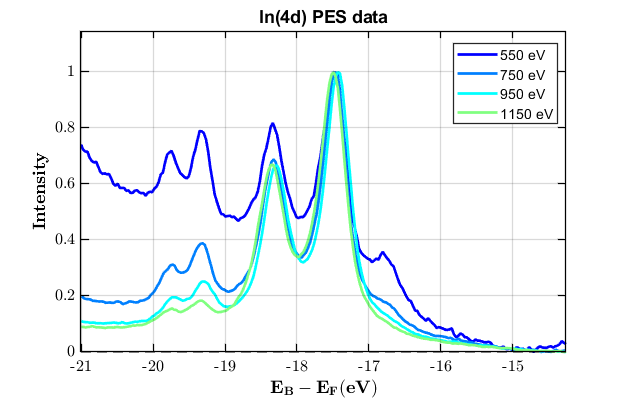

lgnd = {}; for i = 1:length(PES_dat); lgnd{end+1} = string(PES_dat{i}.hv) + " eV"; end
legend(lgnd,'Location','best'); title(sprintf("In(4d) PES data"), 'interpreter', 'none');